close all; clear all; clc
cd(fileparts(matlab.desktop.editor.getActiveFilename));
cd("..\data-engineering\")

Data Engineering Macros

emg_chan_idxs = 192 + [1,2,3,4,11,12,13,14,21,22,23,24,31,32,33,34,41,42,43,44,51,52,53,54,61,62,63,64,71,72,73,74];
dof_idxs = 1:5;

Top 3 human learning rate participants from best to worst

data_dir = "D:/FRM/co-adaptive-learning/";
participant_list = [
    "p-10/healthy/ml/", "p-10/healthy/hl/", "p-10/healthy/cl/" ... 
    "p-05/nonparetic/ml/", "p-05/nonparetic/hl/", "p-05/nonparetic/cl/" ...
    "p-08/paretic/ml/", "p-08/paretic/hl/", "p-08/paretic/cl/"
    ];

## Verify all `.kdf's` exist

for participant_dir = participant_list
    [kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir);
    fprintf("%s\n\t%s\n\t%s\n\t%s\n", participant_dir, kdf_filename, evt_filename, ns5_filename);
end

p-10/healthy/ml/
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/TaskData_20231003-164321.kdf
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/EventParams_20231003-164321.txt
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/20231003-164321-0011.ns5
p-10/healthy/hl/
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/TaskData_20231003-171017.kdf
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/EventParams_20231003-171017.txt
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/20231003-171017-0014.ns5
p-10/healthy/cl/
	D:/FRM/co-adaptive-learning/p-10/healthy/cl/TaskData_20231003-165053.kdf
	D:/FRM/co-adaptive-learning/p-10/healthy/cl/EventParams_20231003-165053.txt
	D:/FRM/co-adaptive-learning/p-10/healthy/cl/20231003-165053-0012.ns5
p-05/nonparetic/ml/
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/TaskData_20230308-181939.kdf
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/EventParams_20230308-181939.txt
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/
p-05/nonparetic/hl/
	D:/FRM/co-adaptive-learning/p-05/nonpar

participant_dir = participant_list(9)

participant_dir = "p-08/paretic/cl/"

[kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir);
[kdf_table, kdf_events] = load_kdf(kdf_filename, evt_filename, emg_chan_idxs, dof_idxs)

kdf_table = 25704×4 table
     NIP Time            Targets           MAV Features        Kalman Output    
    __________    _____________________    ____________    _____________________

    2.5182e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5272e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
     2.538e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5461e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5566e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5665e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5758e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5863e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.5962e+05    0    0   

kdf_events = 27×1 struct array with fields:
    ARD
    ART
    ASD
    Acc
    AllPairs
    ApplyBaseline
    AutoPopType
    AutoThresh
    BAmp
    BFreq
    BadEMGChans
    BadUEAElects
    CAR
    CARType
    CtrlMode
    CtrlSpeed
    ETD
    EventID
    Gain
    HideSphrs
    Jitter
    KEMGExtra
    KGainExt
    KGainFlex
    KThreshExt
    KThreshFlex
    KalmanType
    KinematicSrc
    LinkedDOF
    Log10
    ManualSpikes
    ManualStim
    Map
    MvntMat
    MvntName
    NIPTime
    Outcome
    PauseTraining
    Radius
    StimCell
    StimMode
    StimStepSize
    ThreshMode
    ThreshVal
    Tracking
    TrialCntExt
    TrialCntFlex
    TrialSphrs
    TrialTS
    TargOnTS
    InTargTS
    OutTargTS
    SuccessTS
    FailureTS
    TrainingOn


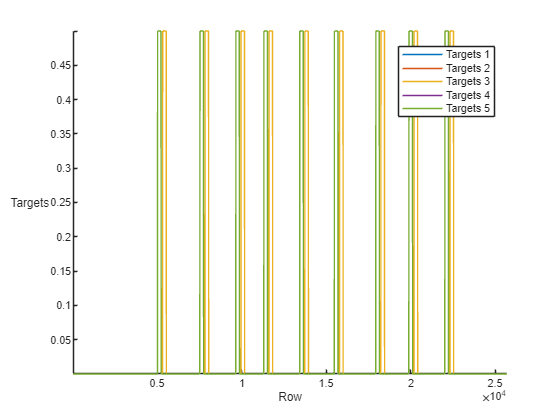

figure
stackedplot(kdf_table(:,"Targets"))

event_starts_nip = uint32([kdf_events.TargOnTS]');
event_stops_nip = uint32([kdf_events.TrialTS])';
event_stops_nip = event_stops_nip(1:end-1);
session_start_nip = event_starts_nip(1);
session_stop_nip = event_stops_nip(end);
kdf_session_start_idx = find(ismember(kdf_table.("NIP Time"), session_start_nip));
kdf_session_stop_idx = find(ismember(kdf_table.("NIP Time"), session_stop_nip));

kdf_timetable = table2timetable(kdf_table(kdf_session_start_idx:kdf_session_stop_idx,:), 'TimeStep', duration(0,0,0,33))

kdf_timetable = 17629×4 timetable
      Time       NIP Time                 Targets                MAV Features                       Kalman Output                   
    ________    __________    _______________________________    ____________    ___________________________________________________

    00:00:00    5.2214e+06      0      0      0      0      0    1×32 double           1          1          1          0          0
    00:00:00    5.2225e+06      0      0      0      0      0    1×32 double           1          1          1          0          0
    00:00:00    5.2235e+06    0.5    0.5    0.5    0.5    0.5    1×32 double           1          1          1          0          0
    00:00:00    5.2244e+06    0.5    0.5    0.5    0.5    0.5 

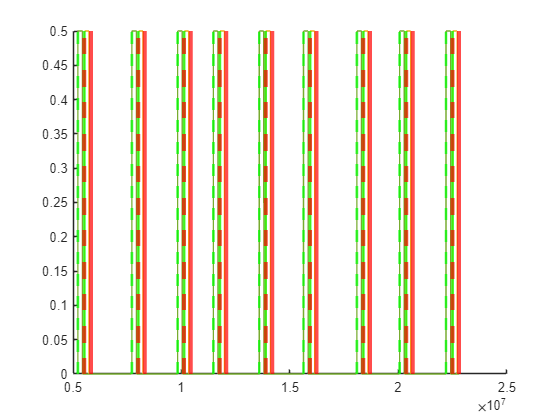

gesture_a_starts_nip = event_starts_nip(1:3:end);
gesture_a_stops_nip = event_stops_nip(1:3:end);
gesture_b_starts_nip = event_starts_nip(2:3:end);
gesture_b_stops_nip = event_stops_nip(2:3:end);

figure
hold on
plot(kdf_timetable.("NIP Time"), kdf_timetable.Targets)
xline(gesture_a_starts_nip, 'g--', LineWidth=2)
xline(gesture_b_starts_nip, 'g', LineWidth=2)
xline(gesture_a_stops_nip, 'r--', LineWidth=3)
xline(gesture_b_stops_nip, 'r', LineWidth=3)
hold off
box off

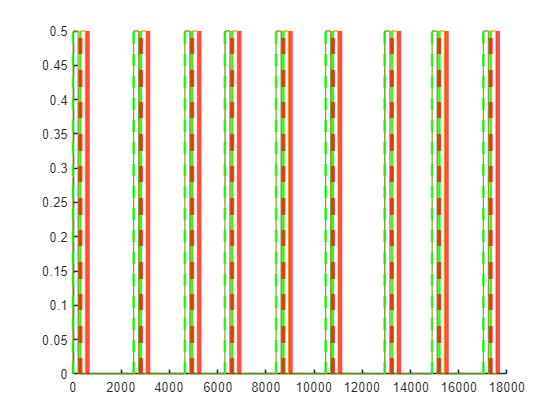

gesture_a_starts_idx = find(ismember(kdf_timetable.("NIP Time"), gesture_a_starts_nip));
gesture_a_stops_idx = find(ismember(kdf_timetable.("NIP Time"), gesture_a_stops_nip));
gesture_b_starts_idx = find(ismember(kdf_timetable.("NIP Time"), gesture_b_starts_nip));
gesture_b_stops_idx = find(ismember(kdf_timetable.("NIP Time"), gesture_b_stops_nip));
figure
hold on
plot(kdf_timetable{:,"Targets"})
xline(gesture_a_starts_idx, 'g--', LineWidth=2)
xline(gesture_b_starts_idx, 'g', LineWidth=2)
xline(gesture_a_stops_idx, 'r--', LineWidth=3)
xline(gesture_b_stops_idx, 'r', LineWidth=3)
hold off
box off

% Extract the participant id using regular expression
p_id_str = regexp(participant_dir, '\d+', 'match');
p_id = str2double(p_id_str{1});

% Extract the substring for the controller type
ctrlr_types = ["ml", "cl" "hl"];
ctrlr_str = [];
for ctrlr_type = ctrlr_types
    if contains(participant_dir, ctrlr_type)
        ctrlr_str = ctrlr_type;
    end
end
if isempty(ctrlr_str)
    error('No valid unit found in the string');
end
csv_filename = sprintf('..\\..\\temp-data\\p_%02d-%s\\p_%02d-%s-kdf-mav.csv', p_id, ctrlr_str, p_id, ctrlr_str)

csv_filename = '..\..\temp-data\p_08-cl\p_08-cl-kdf-mav.csv'

writetimetable(kdf_timetable, csv_filename)
csv_filename = sprintf('..\\..\\temp-data\\p_%02d-%s\\p_%02d-%s-kdf-mav-gesture_idxs.csv', p_id, ctrlr_str, p_id, ctrlr_str)

csv_filename = '..\..\temp-data\p_08-cl\p_08-cl-kdf-mav-gesture_idxs.csv'

writetable(table(gesture_a_starts_idx, gesture_a_stops_idx, gesture_b_starts_idx, gesture_b_stops_idx), csv_filename)

function [kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir)
kdf_regex = "Task*.kdf";
evt_regex = "Event*.txt";
ns5_regex = "*.ns5";

dir_out = dir(strcat(data_dir, participant_dir, kdf_regex));
kdf_filename = strcat(data_dir, participant_dir, dir_out.name);

dir_out = dir(strcat(data_dir, participant_dir, evt_regex));
evt_filename = strcat(data_dir, participant_dir, dir_out.name);

dir_out = dir(strcat(data_dir, participant_dir, ns5_regex));
ns5_filename = convertStringsToChars(strcat(data_dir, participant_dir, dir_out.name));
end
function [kdf_table, kdf_events] = load_kdf(kdf_filename, evt_filename, emg_chan_idxs, dof_idxs)
[Kinematics, Features, Targets, Kalman, NIPTime] = jag_deng_utils.read_kdf_file(kdf_filename);
kdf_table = table(NIPTime', Targets(dof_idxs,:)', Features(emg_chan_idxs,:)', Kalman(dof_idxs, :)', ...
    'VariableNames', ["NIP Time", "Targets", "MAV Features", "Kalman Output"]);
kdf_events = jag_deng_utils.read_event_params(evt_filename);
end
function [ns5_nip, ns5_start_idxs, ns5_stop_idxs] = compute_ns5_idxs(event_starts_nip, event_stops_nip, kdf_nip_ref, ns5_length)
% ns5_nip = (kdf_nip_ref:(kdf_nip_ref+ns5_length-1))';
ns5_nip = flip(kdf_nip_ref:-1:kdf_nip_ref-ns5_length+1)';
ns5_start_idxs = find(ismember(ns5_nip, event_starts_nip));
ns5_stop_idxs = find(ismember(ns5_nip, event_stops_nip));
end